data = input

fs = 12800;
ts = 1/fs;
t = 0:ts:DSP_LEN*ts-ts;
plot(t',data(1:DSP_LEN));
grid on;
%plot(input(1:inputLen))
clear ts t len


fftOut = fft(data,DSP_LEN);

fftRe = real(fftOut);
fftIm = imag(fftOut);
fftAbs = abs(fftOut(1:DSP_LEN/2))/DSP_LEN*2;
fftAbs(1)=fftAbs(1)/2

fftAbs = 	1.0e+04 *

    3.2775
    0.0001
    0.0002
    0.0003
    2.7493
    0.0003
    0.0002
    0.0001
    0.0067
    0.0000


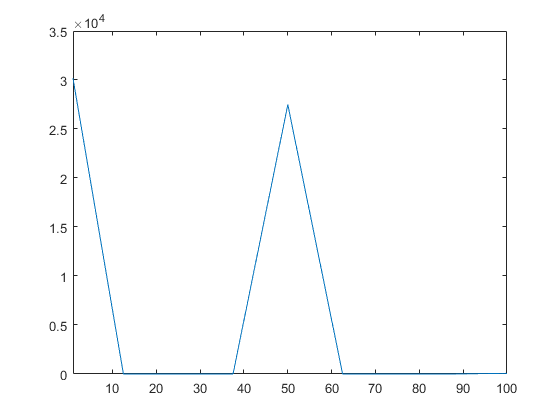


f = fs*(0:(DSP_LEN/2)-1)/DSP_LEN;
plot(f,fftAbs)
xlim([1 100])


clear fftAbs  f fftOut